[A, B, C, D, G] = nominal();
[gm, pm, wcg, wcp] = margin(G)

gm = Inf

pm = 90

wcg = Inf

wcp = 1.0000

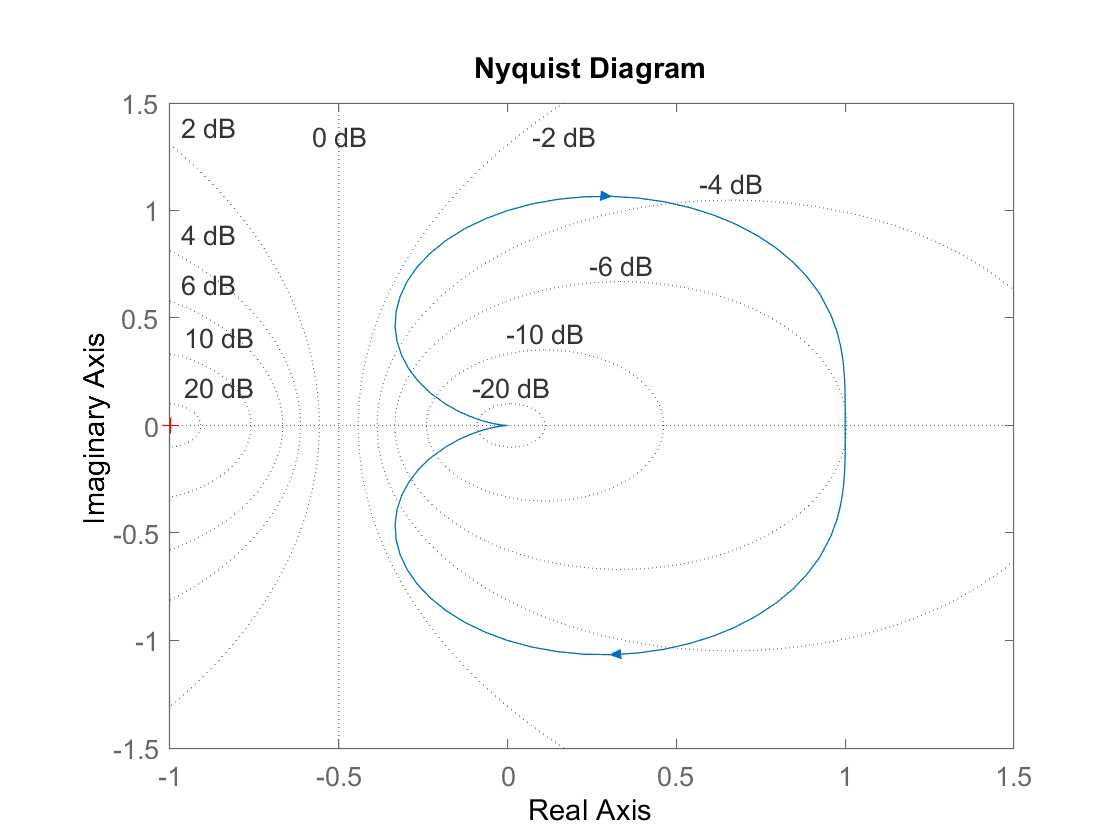

figure;
nyquist(G);
%title('Nyquist Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

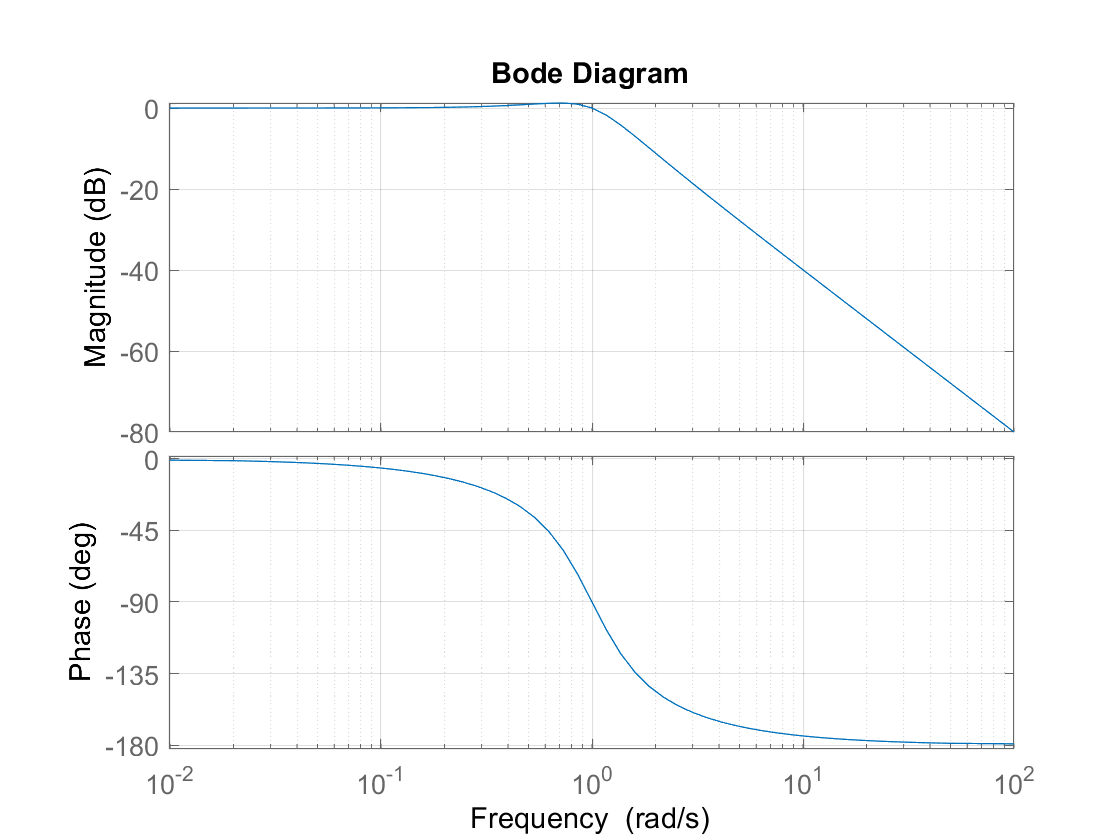


% Bode plot
figure;
bode(G);
%title('Bode Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/bode_G.png', '-dpng', '-r300');

syms k real

% closed-loop matrix
A_cl = A - B * k * C;

eigvals = eig(A_cl);
stability_range = solve(real(eigvals) < 0, k, 'Real', true);

% Display result
disp('Range of K for stability:')

Range of K for stability:


disp(stability_range)

$$0$$

k_vals = linspace(-10, 10, 1000);   % Negative k values

% Plot root locus
figure; hold on;
rlocus(G, k_vals);
xlabel('Real Axis')
ylabel('Imaginary Axis')
title('Root Locus')
grid on;
legend('Positive k', 'Negative k')

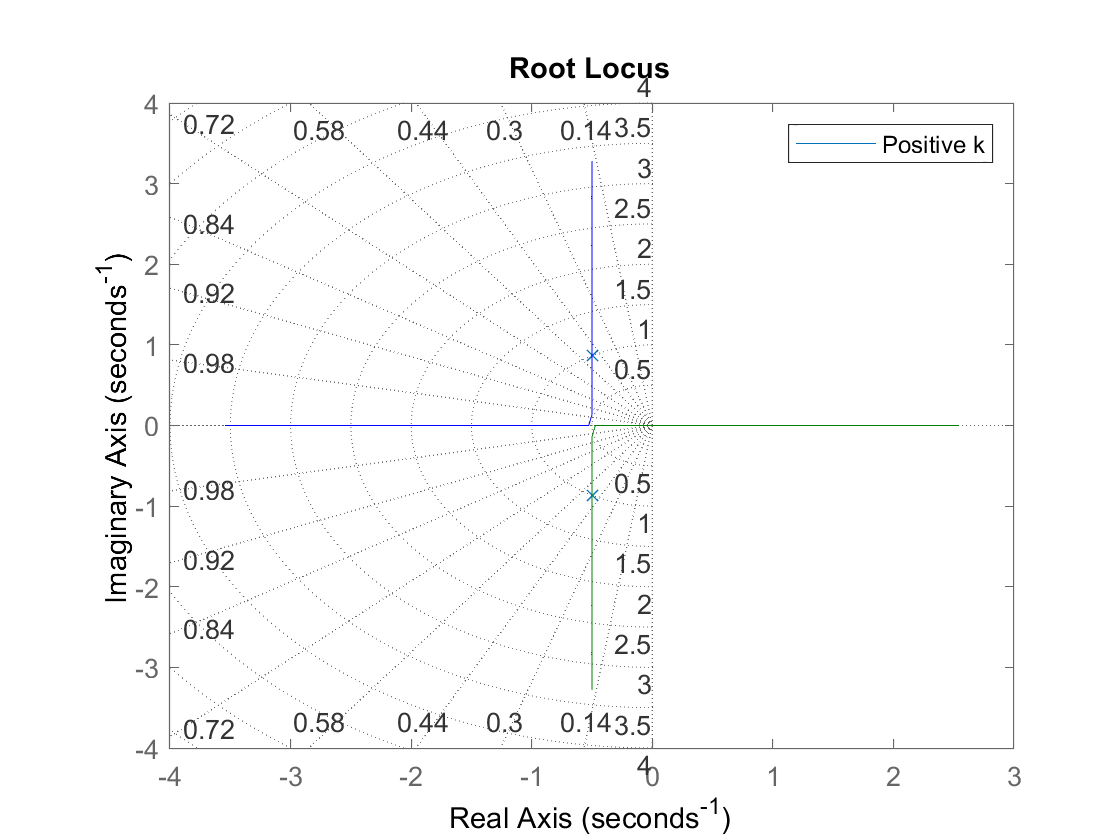

hold off;
print(gcf, 'figures/rlocus_G.png', '-dpng', '-r300');

G_dashed = Hinfty(G);

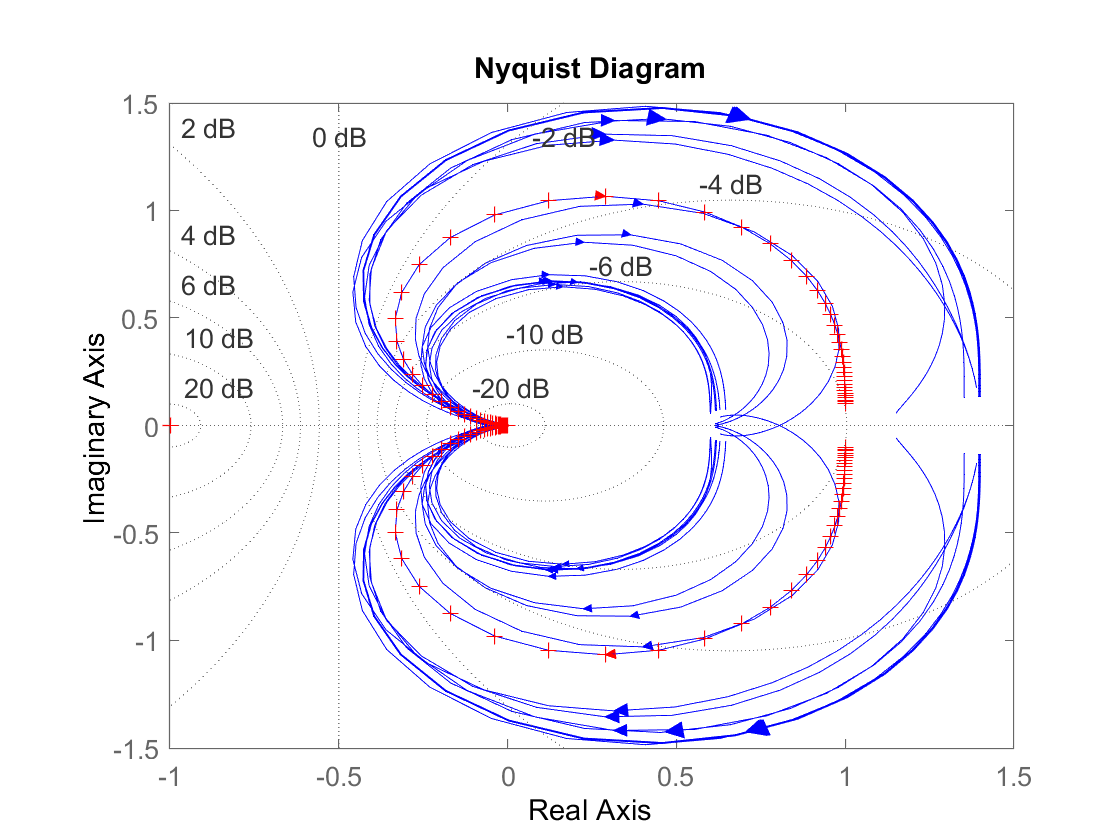

figure;
nyquist(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120));
%title('Nyquist Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

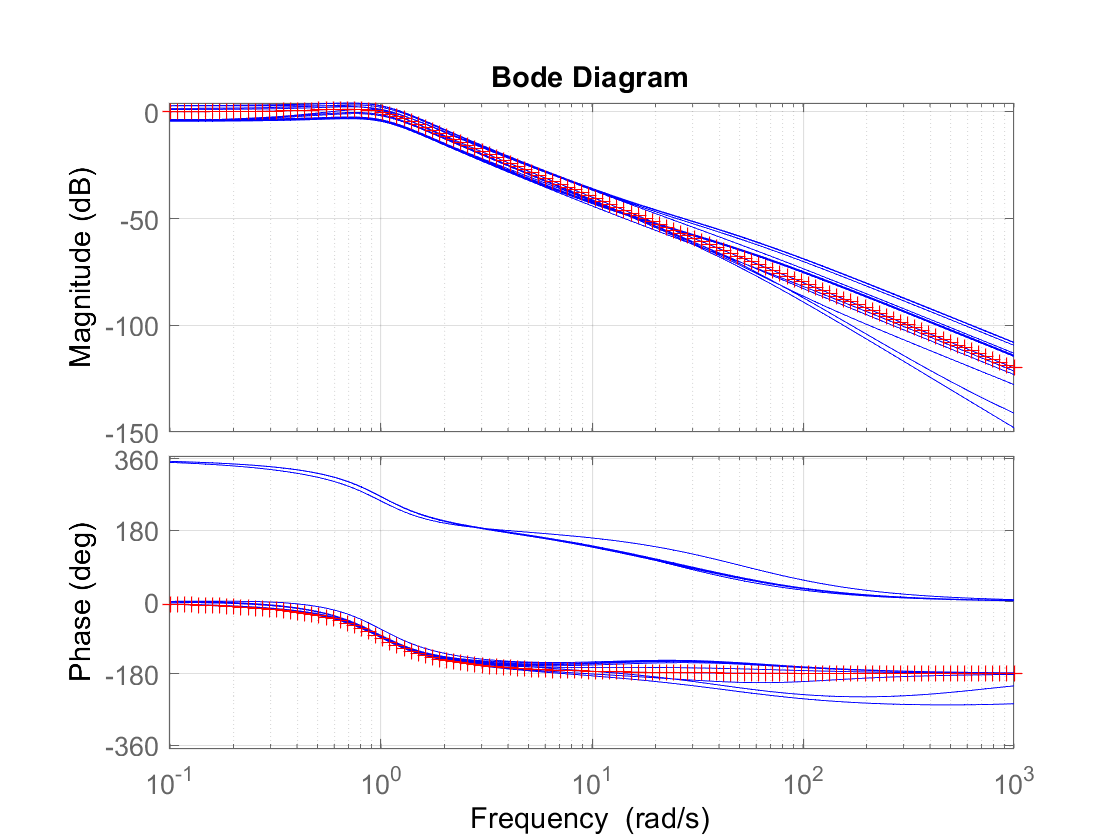


% Bode plot
figure;
bode(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120))
%title('Bode Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/bode_G.png', '-dpng', '-r300');

syms s m c_p Delta_p c_v Delta_v omega

den1 = m * s^2 + (c_v + Delta_v) * s + (c_p + Delta_p);
den2 = m * s^2 + c_v * s + c_p;

Delta = (c_p + Delta_p) / den1 - c_p / den2;

Delta_expanded = expand(Delta);
Delta_collected = collect(Delta_expanded, [s, Delta_p, Delta_v]);

numer = (c_p + Delta_p) * den2 - c_p * den1;
denom = den1 * den2;
Delta_combined = numer / denom;

Delta_simplified = simplify(Delta_combined)

$$Delta\_simplified = \frac{s\,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,s\right)}{\left(m\,s^{2}+c_{v}\,s+c_{p}\right)\,\left(\Delta_{p}+c_{p}+\Delta_{v}\,s+c_{v}\,s+m\,s^{2}\right)}$$

b = subs(Delta_simplified, s, 1j * omega)

$$b = \frac{\omega \,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,\omega \,\mathrm{i}\right)\,\mathrm{i}}{\left(-m\,\omega^{2}+\mathrm{i}\,c_{v}\,\omega +c_{p}\right)\,\left(\Delta_{p}+c_{p}-m\,\omega^{2}+\Delta_{v}\,\omega \,\mathrm{i}+c_{v}\,\omega \,\mathrm{i}\right)}$$

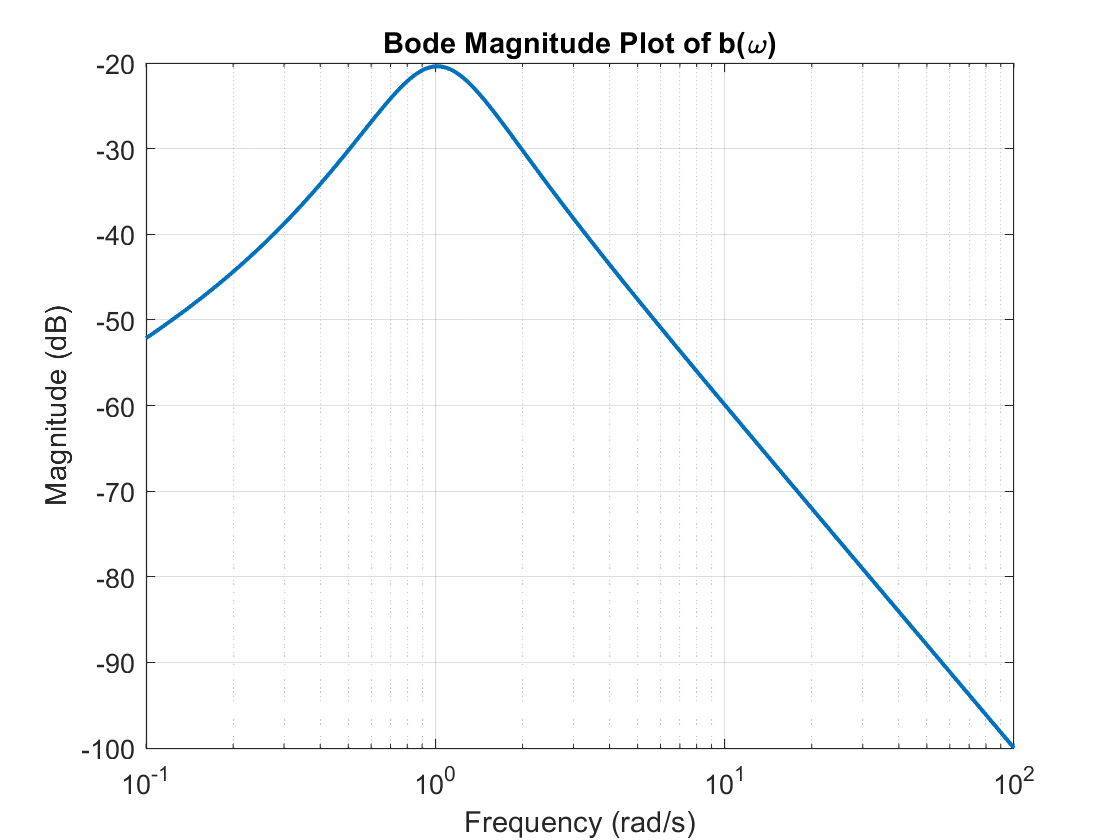

params = struct('m', 1.0, 'c_p', 1.0, 'Delta_p', 0.1, 'c_v', 1.0, 'Delta_v', 0.075);
b_func = matlabFunction(abs(subs(b, params)), 'Vars', omega);

omega_vals = logspace(-1, 2, 400); % Frequency range from 0.1 to 100 rad/s
b_magnitude = b_func(omega_vals);
figure;
semilogx(omega_vals, 20*log10(b_magnitude), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Magnitude Plot of b(\omega)');
grid on;

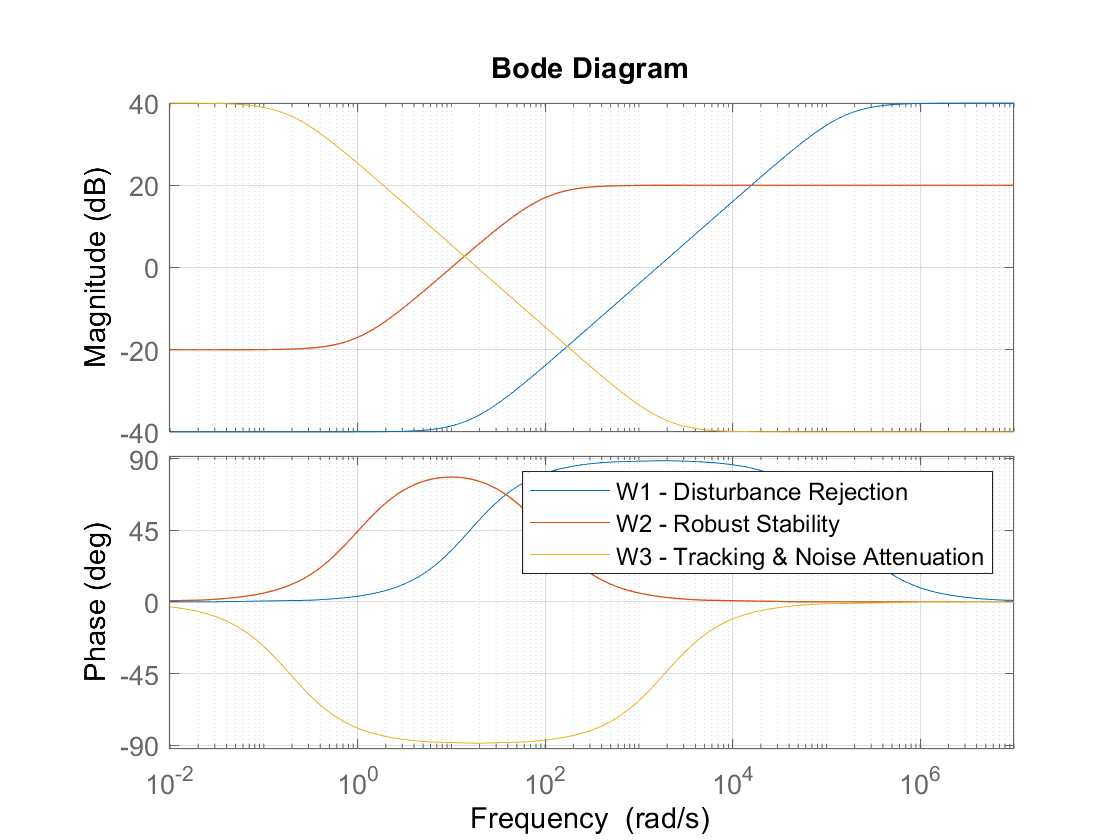

W1 = makeweight(0.01, 500*pi, 100);
W2 = makeweight(0.1, 10, 10);
W3 = makeweight(100, 6*pi, 0.01);
bode(W1, W2, W3), grid on;
legend('W1 - Disturbance Rejection', 'W2 - Robust Stability', 'W3 - Tracking & Noise Attenuation');

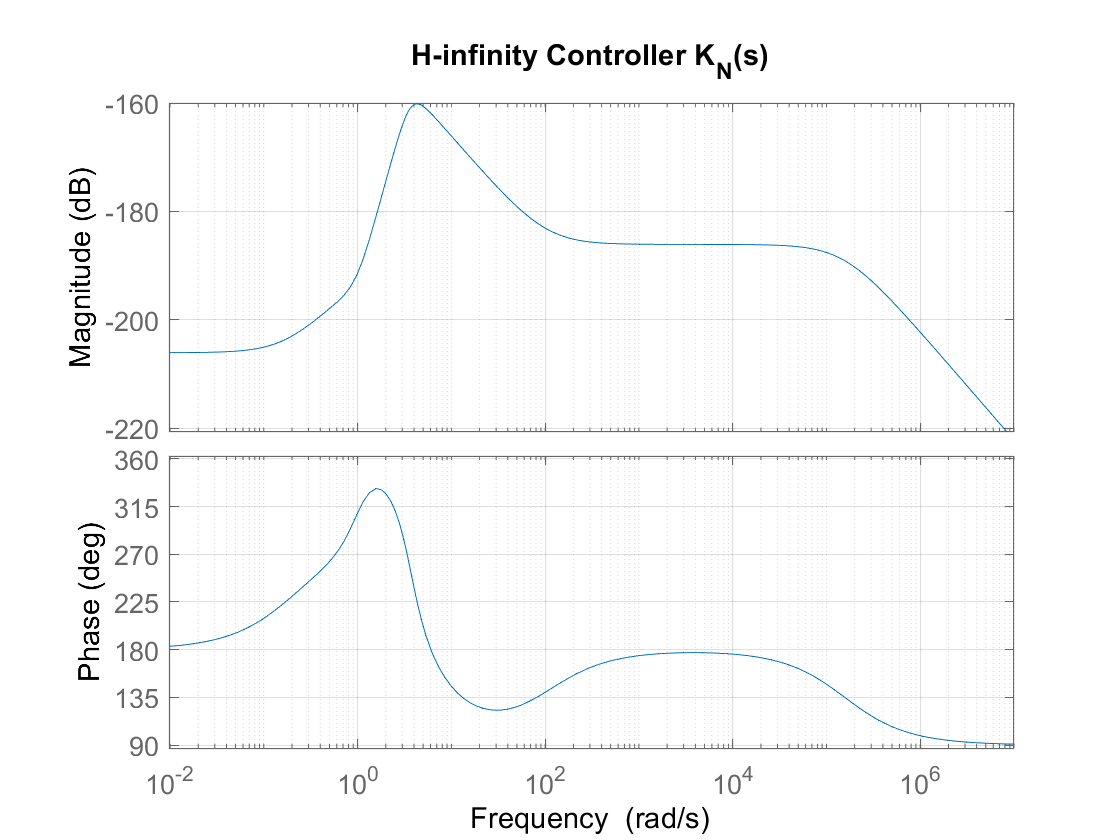

[K_N, CL, gamma] = mixsyn(G, W1, W2, W3);
bode(K_N), grid on;
title('H-infinity Controller K_N(s)');

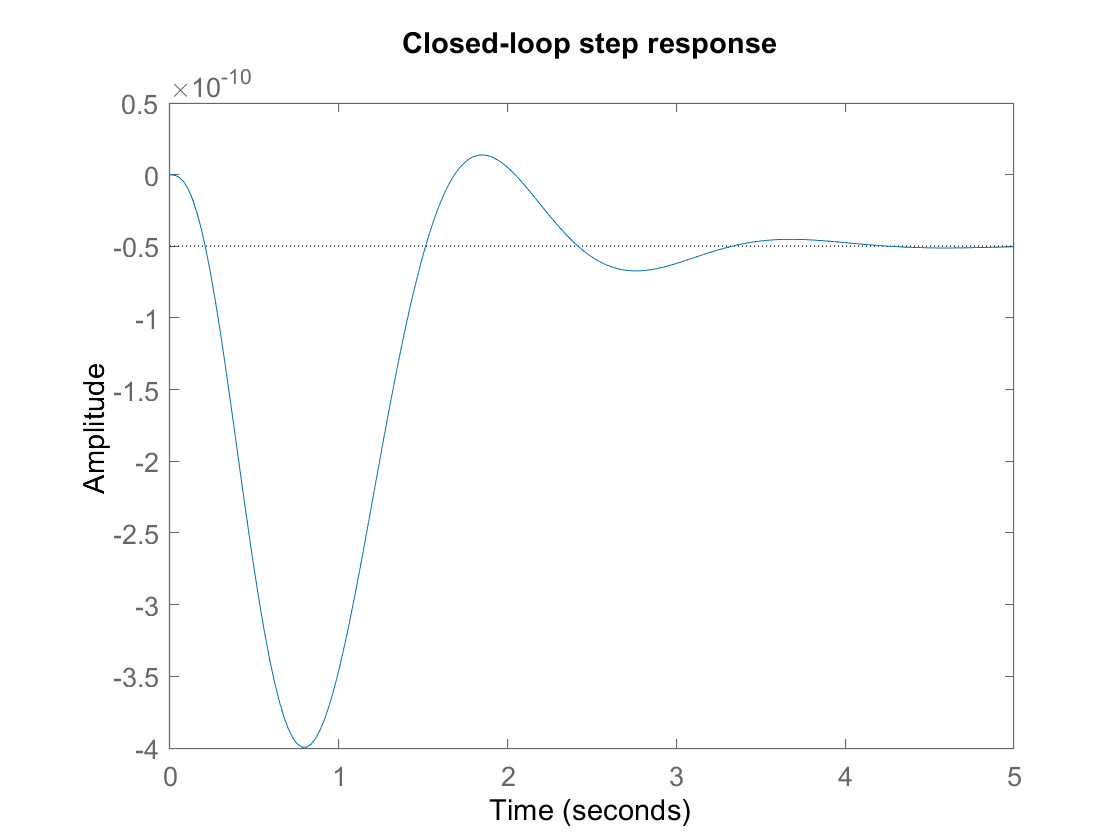

T = feedback(G*K_N, 1);
step(T);
title('Closed-loop step response');


bGK = calc_bGK(G, K_N)

Computed b(G, K) = 0.6547


bGK = 0.6547